# Miniprojekt 4 - Nøjagtig frekvensmåling

## Indledning

Vi vil i denne opgave anvende digital signalbehandling til at lavfiltere et støjfyldt signal indeholdene 40 harmoniske overtoner, som skal illustriere et signal fra en Genset (en motor kombineret af en forbrændingsmotor og elektrisk generator). Efter at signalet er filtreret vil vi gennem zero crossing finde nulgennemgangen af signalet ved samplenummer (sampleinkeks) ved to samples på hver sin side af henholdsvis den positive y-akse og negative y-aske. Herved kan tiden mellem de to samples findes og se om de specifikke opgavebeskrivelses krav opfyldes.

## Formål

Vi vil designe forskellige 2. ordens IIR filtere til filtrering af signalet x2 med overtonerene, og bruge den bedst egnede til udøvelse af zero crossing til at kunne opfylde kravsspicifikationerne. 

Krav til opgaven:

- Både x1 og x2 har en grundfrekvens på 50,1111 Hz

- Afvigelsen må maksimalt være ±10mHz

- Samplingsfrekvensen skal være 10kHz

- Filteret skal være et 2. ordens IIR filter

## Analyse

Analysen til dette miniprojekt om Zero crossing algoritme er beskrevet i opgavebeskrivelsen. Vi vælger derfor ikke at beskrive det yderligere, da denne beskrivelse er fyselsgørende nok til udførelse af denne opgave. Vi referer derfor til opgavebeskrivelsen om analysen til dette Miniprojekt.

## Opgaven

### Tids- og frekvensanalyse

clear;
load('signal_IEC60255_50_1111Hz.mat')
fs = signal.fs; % Samplingfrekvens på 10 kHz
x1 = signal.x1; % Det rene sinus signal
x2 = signal.x2; % Signal med 40 harmoniske overtoner
N = length(x1); % Antal samples
gF = 50.1111;   % Grundfrekvens for begge signaler

Først vil de to signaler blive plottet med en tidsakse i intervallet fra 0 til 55 ms.

Periode tiden findes.

ts = 1/fs;      % Sample tid

Nu bestemmes tiden for plottet.

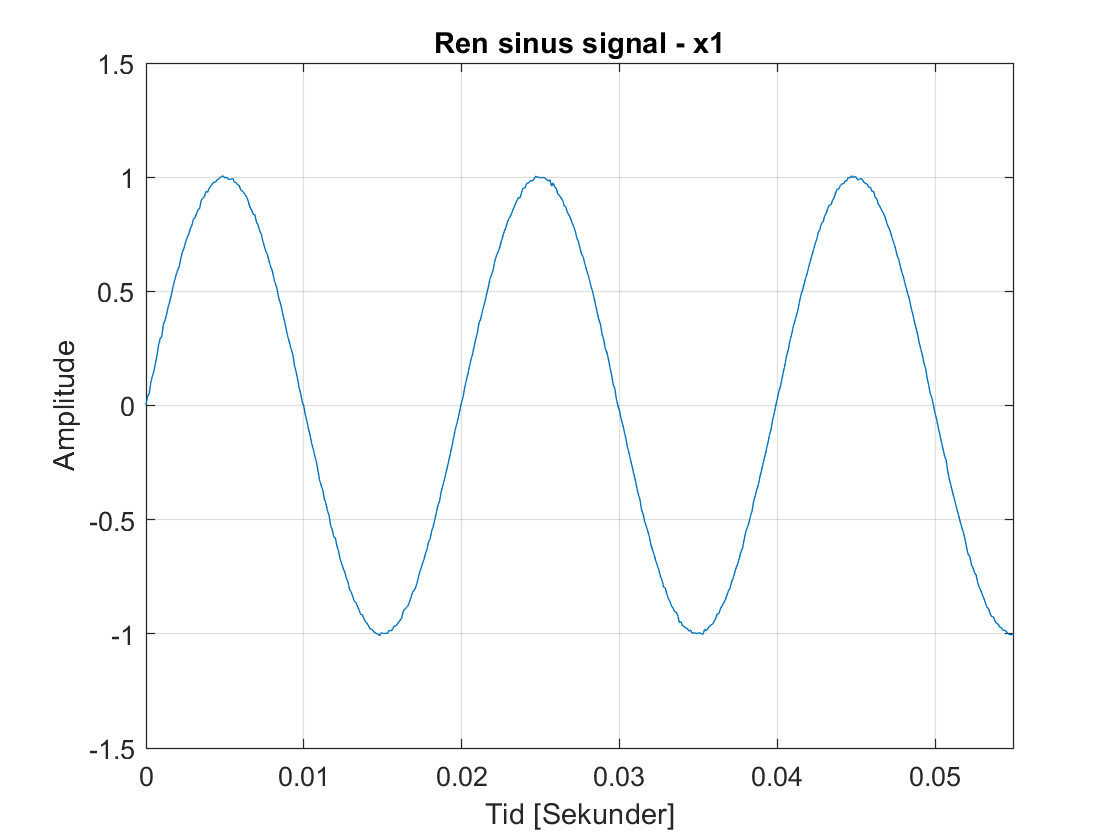

t = (0:N-1).*ts;    % Varighed i tid
plot(t,x1)          % Plot af Ren sinus signal - x1
xlim([0 0.055])     % Plottes for de første 0.055 sekunder
grid on
title('Ren sinus signal - x1')
xlabel('Tid [Sekunder]')
ylabel('Amplitude')

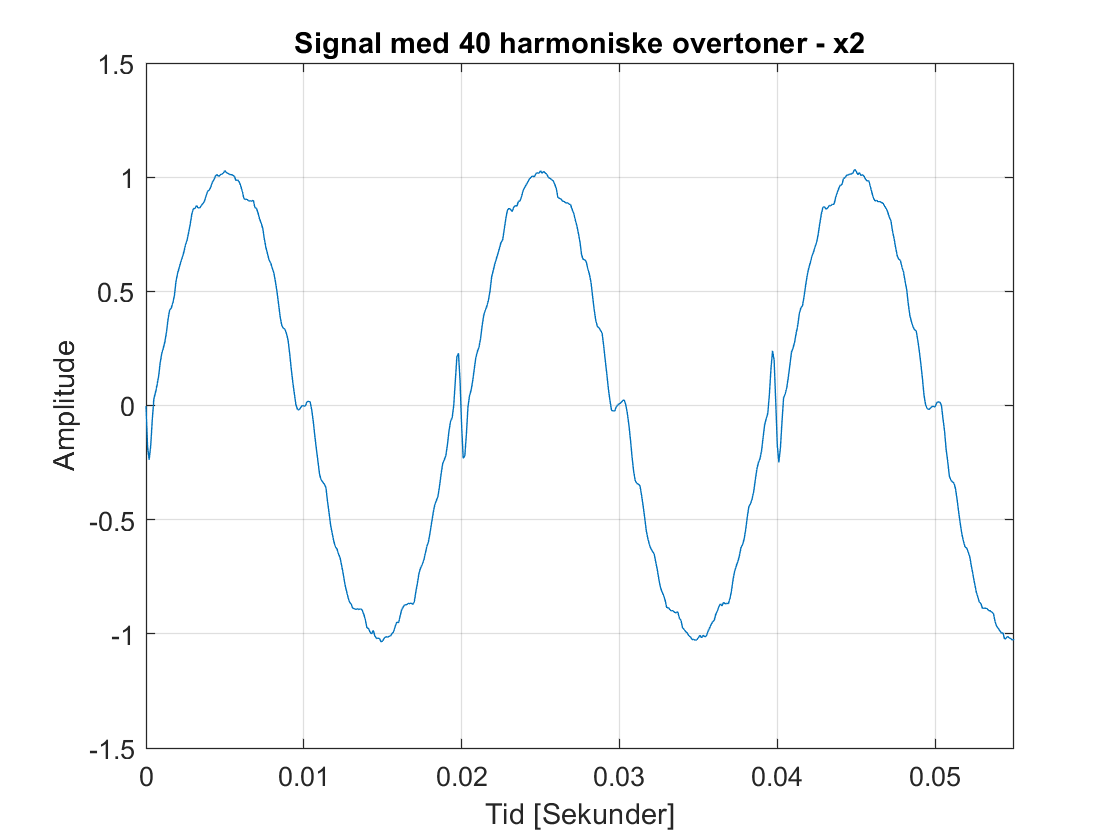

plot(t,x2)      % Plot af signalet med 40 harmoniske overtoner - x2
xlim([0 0.055]) % Plottes for de første 0.055 sekunder
grid on
title('Signal med 40 harmoniske overtoner - x2')
xlabel('Tid [Sekunder]')
ylabel('Amplitude')

Nu beregnes DFT for signalerne, samt plot af amplityde spektrene. Men først vil vi bestemme de nødvendige antal samples, for at opnå en afvielse på maksimalt +- 10mHz. 

delta_f = 0.01;  % Frekvens opløsningen: 0.01 = 10mHz
Nny = fs/delta_f % Minimum antal samples 

Nny = 1000000

Da FFT'en tager sampels med $2^n$, så findes den exponent der er efter 500.000 

Nny = 2^nextpow2(Nny)     % Minimum antal samples i n'te potent, fordi FFT bruger n'te potent

Nny = 1048576

DFTx1 = 2/N*abs(fft(x1,Nny)); % DFT for x1
DFTx2 = 2/N*abs(fft(x2,Nny)); % DFT for x2
k = 0:Nny-1;                  % Frekvens pins
f = k*fs/Nny;                 % Frekvensakse

Nu plottes amplitudespektret for både det rene signal og signalet med 40 harmoniske overtoner op til nyquist.

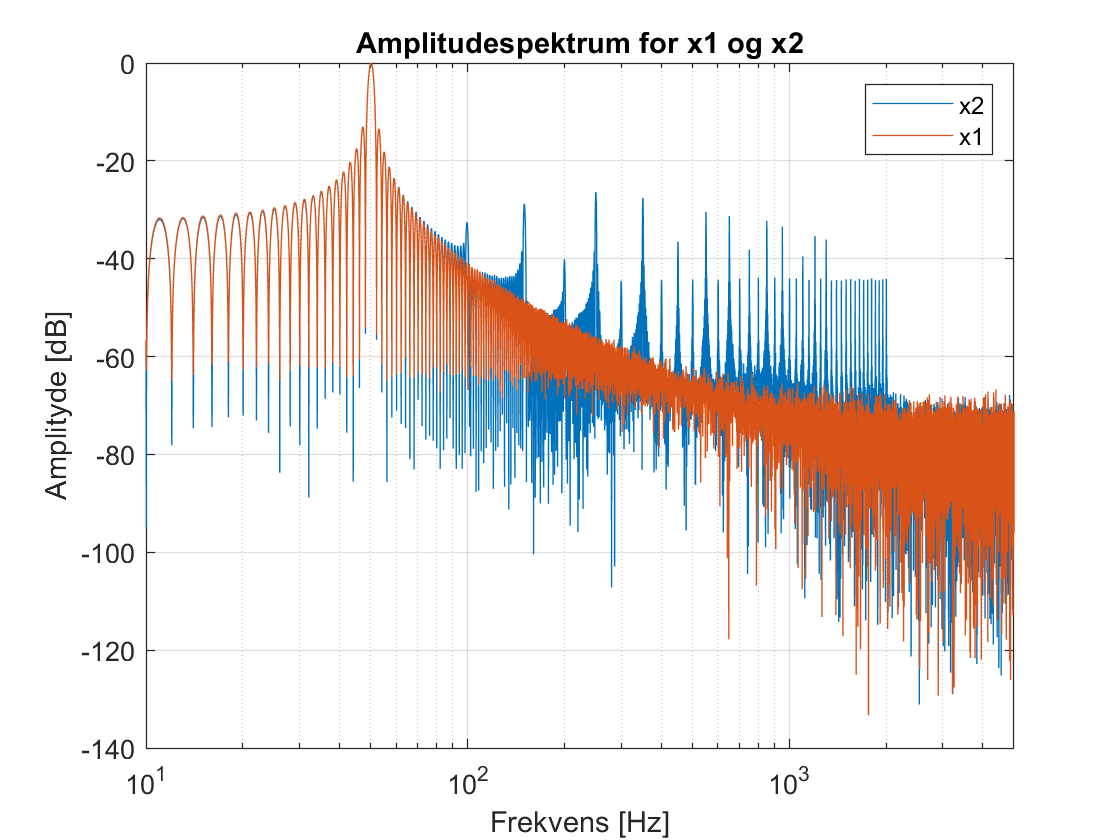

semilogx(f,20*log10(DFTx2)) % Plot af x2 med logaritmisk akse
hold on
semilogx(f,20*log10(DFTx1)) % Plot af x1 med logaritmisk akse
hold off
xlim([10,fs/2]);            % x-akse skalering
grid on
title('Amplitudespektrum for x1 og x2')           
xlabel('Frekvens [Hz]')
ylabel('Amplityde [dB]')
legend("x2","x1")

Vi vil nu finde den dominerede frekvens, og herudfra se om vi opfylder kravet om afvielse af frekvensopløsningen

[max_amplitudex2, max_frekvens_binx2] = max(DFTx2(floor(1:end/2))); % Finder max- amplitude og frekvens
max_frekvensx2 = (max_frekvens_binx2/Nny) * fs                      % Finder grundfrekvensen

max_frekvensx2 = 50.1156

afvigelse = (max_frekvensx2-gF) % Afvielse på 0.0045 = 4.5mHz

afvigelse = 0.0045

Det ses ud fra afvigelsen af den kun er 4.5mHz hvilket er minder end 10mHz, som var kravet.

For at finde de harmoniske frekvenskomponenter i signalet x2, plottes amplitudespektret med lineær frekvensakse, for at kunne tælle overtonerne.

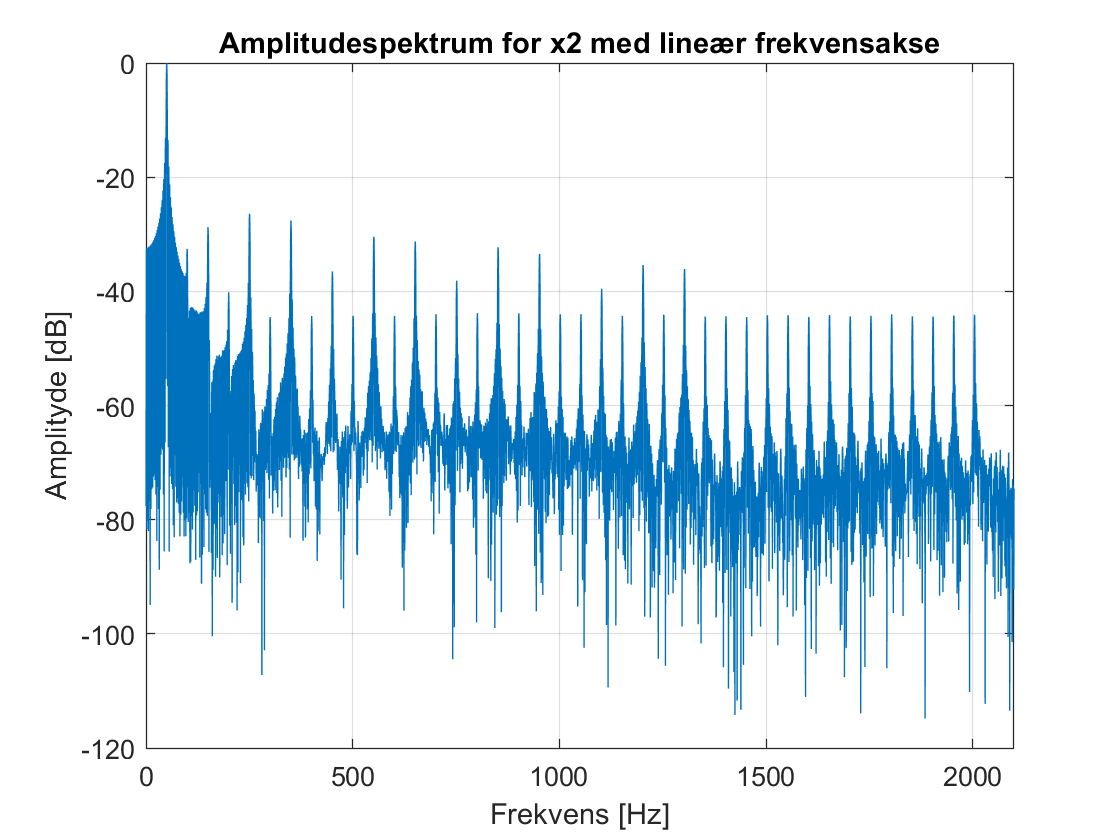

plot(f,20*log10(DFTx2)) % Plot af x2 med lineær akse
grid on
title('Amplitudespektrum for x2 med lineær frekvensakse')
xlabel('Frekvens [Hz]')
ylabel('Amplityde [dB]')
xlim([0,2100]); % x-akse skalering

Ud fra plottet ovenfor kan det tælles at der er 40 overtoner. Vi har herved fundet de harmoniske frekvenskomponenter af signalet.

### Hurtig frekvensestimering med zero crossing

#### Filtrering

Nu designes tre forskellige 2. ordens lavpas IIR filtre for at filtre de ikke ønskede højere harmoniske frekvenser fra. Alle filtrene skal have en cut-off til noget højere end den dominerende frekvens.

fc = max_frekvensx2 % Cutoff frekvensen bestemmes til vores beregnede grundfrekvensen

fc = 50.1156

Der startes med Butterworth filtret. 

[butterB,butterA] = butter(2,2*fc/fs,"low");    % B og A koeficienter for Butterworth filtret
%fvtool(butterB,butterA);                       % Plot af Butterworth filtret

Chebyshev type 1 filteret designes.

[chebyB,chebyA] = cheby1(2,12,2*fc/fs,"low");   % B og A koeficienter for Chebyshev type 1 filtret
%fvtool(chebyB,chebyA);                         % Plot af Chebyshev type 1 filtret

Chebyshev type 2 filteret designes.

[cheby2B,cheby2A] = cheby2(2,20,2*fc/fs,"low"); % B og A koeficienter for Chebyshev type 2 filtret
%fvtool(cheby2B,cheby2A);                       % Plot af Chebyshev type 2 filtret

Et eliptisk filtre laves.

[ellipB,ellipA] = ellip(2,1,50,2*fc/fs,"low");  % B og A koeficienter for et eliptisk filtret
%fvtool(ellipB,ellipA);                         % Plot af eliptisk filtret

Nu påtrykkes signalerne de forskellige filtre.

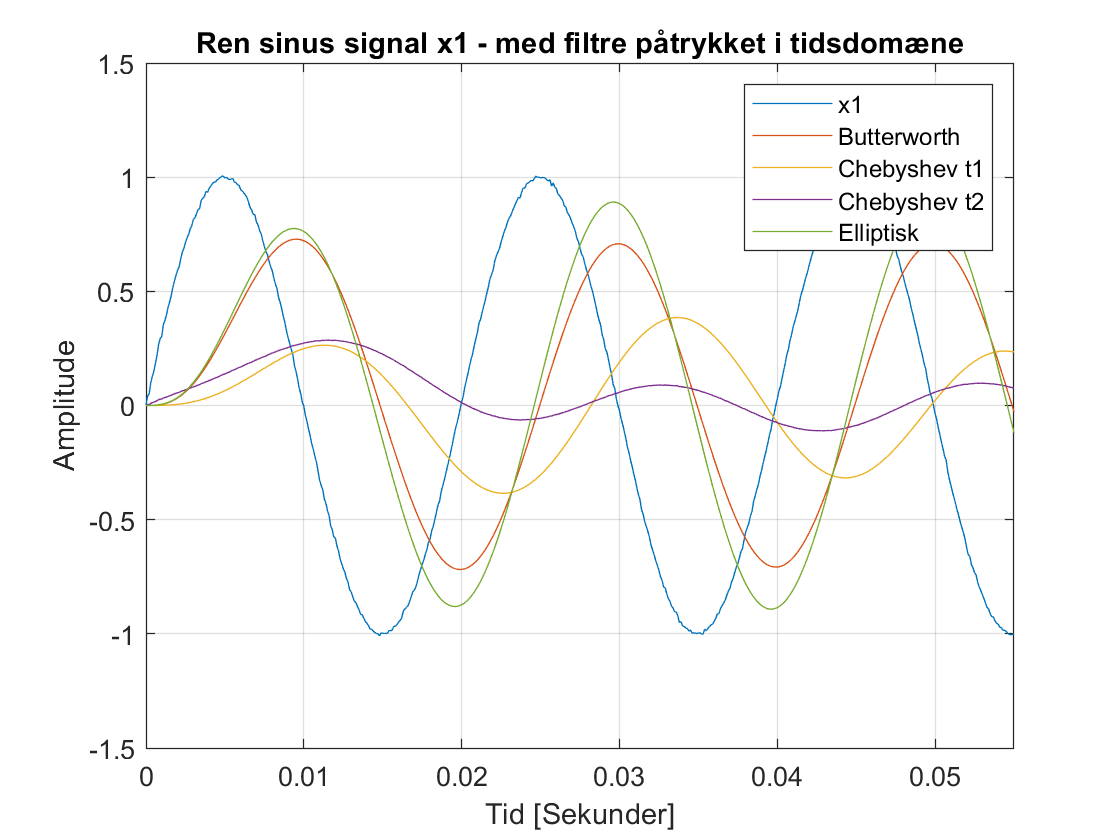

x1butter = filter(butterB,butterA,x1);  % Signal x1 påtrykkes med Butterworth filtret
x1cheby = filter(chebyB,chebyA,x1);     % Signal x1 påtrykkes med Chebyshev type 1 filtret
x1cheby2 = filter(cheby2B,cheby2A,x1);  % Signal x1 påtrykkes med Chebyshev type 2 filtret
x1ellip = filter(ellipB,ellipA,x1);     % Signal x1 påtrykkes med et eliptisk filtret

plot(t,x1,t,x1butter,t,x1cheby,t,x1cheby2,t,x1ellip) % Plot af x1 samt de 4 påtrygte filtre
xlim([0 0.055])                                      % Plottes for de første 0.055 sekunder
title('Ren sinus signal x1 - med filtre påtrykket i tidsdomæne')
grid on
xlabel('Tid [Sekunder]')
ylabel('Amplitude')
legend("x1","Butterworth","Chebyshev t1", "Chebyshev t2", "Elliptisk")

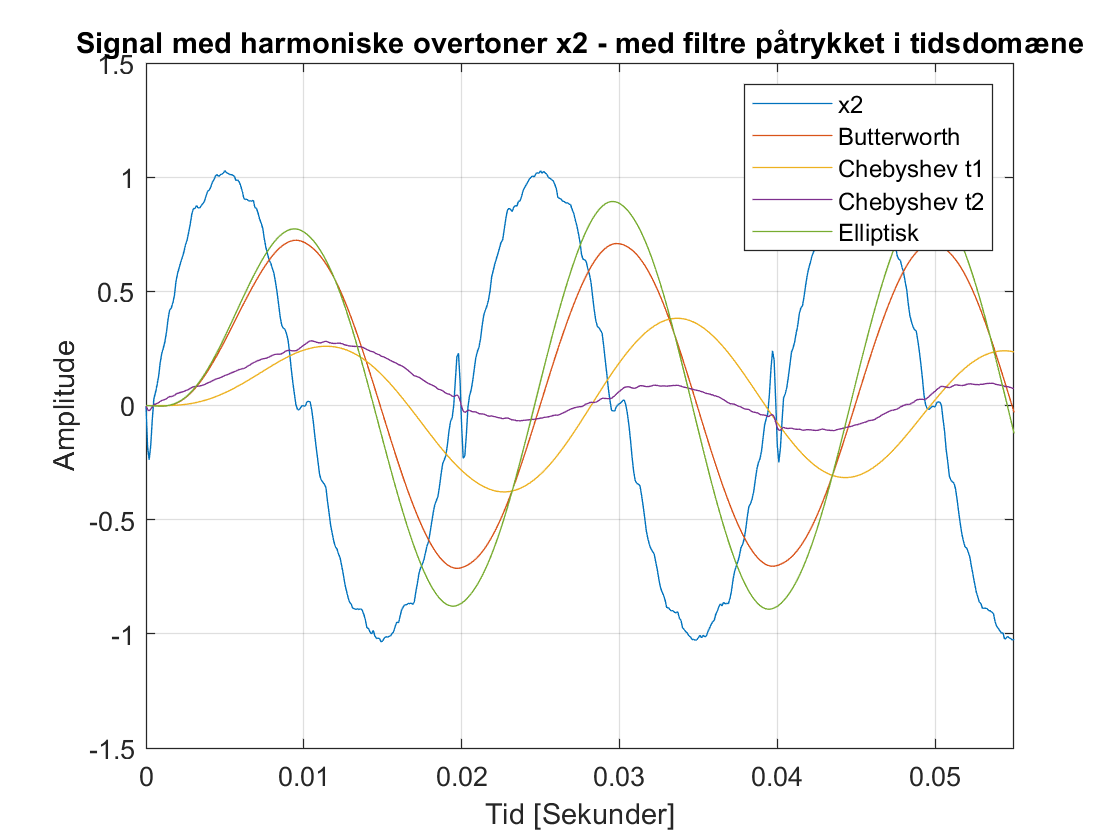

x2butter = filter(butterB,butterA,x2);  % Signal x2 påtrykkes med Butterworth filtret
x2cheby = filter(chebyB,chebyA,x2);     % Signal x2 påtrykkes med Chebyshev type 1 filtret
x2cheby2 = filter(cheby2B,cheby2A,x2);  % Signal x2 påtrykkes med Chebyshev type 2 filtret
x2ellip = filter(ellipB,ellipA,x2);     % Signal x2 påtrykkes med et eliptisk filtret

plot(t,x2,t,x2butter,t,x2cheby,t,x2cheby2,t,x2ellip) % Plot af x2 samt de 4 påtrygte filtre
xlim([0 0.055])                         % Plottes for de første 0.055 sekunder
title('Signal med harmoniske overtoner x2 - med filtre påtrykket i tidsdomæne')
grid on
xlabel('Tid [Sekunder]')
ylabel('Amplitude')
legend("x2","Butterworth","Chebyshev t1", "Chebyshev t2", "Elliptisk")

Det ses ud fra overstående plot af de 4 påtrygte filtre på x2 at **Elliptisk** er bedst på den måde at den har filtrere støjet væk, og minimere amplituden mindst muligt. Men det ses også at Butterworth filteret næsten er et lige så godt filter, men at den få en lidt laverere amplitude end ved det elliptiske filter. Derudover ses det at Chebyshev type 2 er dårligst, og at der stadig forkommer støj i signalet.

Amplitudespektret findes ved brug af DFT. Først for x1.

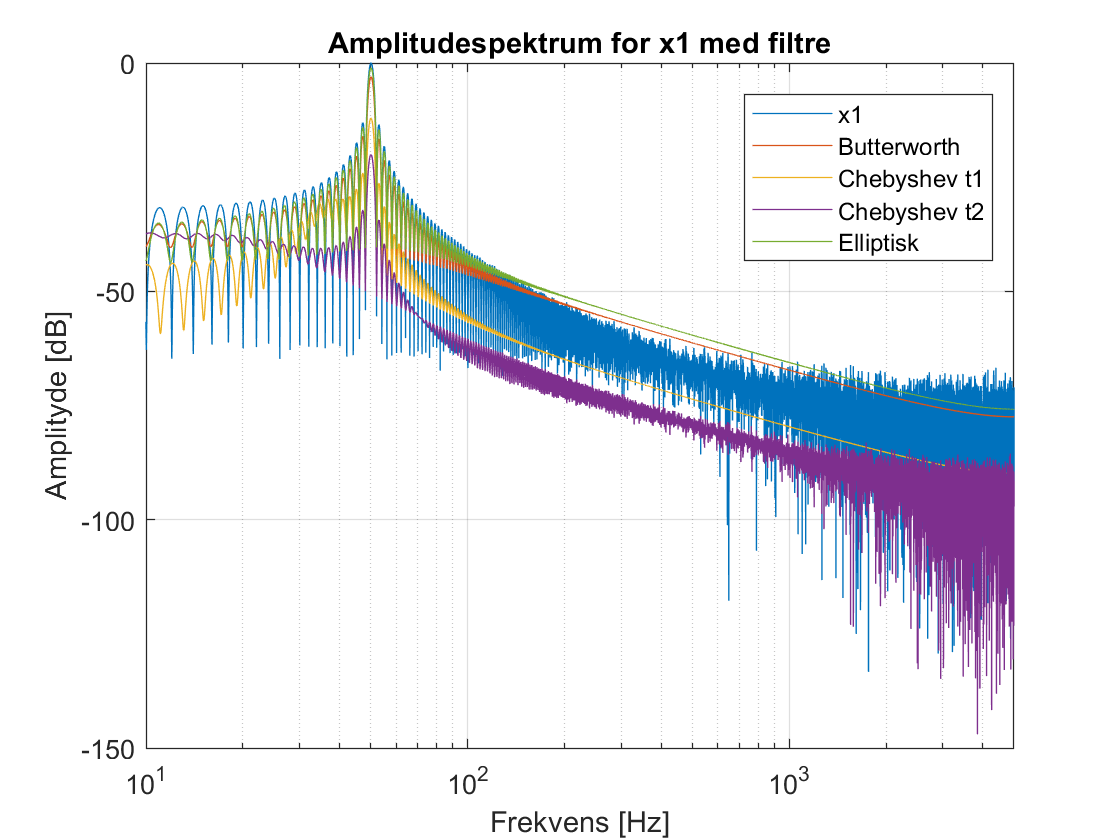

DFTx1butter = 2/N * abs(fft(x1butter,Nny));   % DFT x1 af Butterworth filtret
DFTx1cheby = 2/N * abs(fft(x1cheby,Nny));     % DFT x1 af Chebyshev type 1 filtret
DFTx1cheby2 = 2/N * abs(fft(x1cheby2,Nny));   % DFT x1 af Chebyshev type 2 filtret
DFTx1ellip = 2/N * abs(fft(x1ellip,Nny));     % DFT x1 af et eliptisk filtret

semilogx(f,20*log10(DFTx1))                   % Plot af x1 samt de 4 påtrygte filtre
hold on
semilogx(f,20*log10(DFTx1butter))       
semilogx(f,20*log10(DFTx1cheby))        
semilogx(f,20*log10(DFTx1cheby2))       
semilogx(f,20*log10(DFTx1ellip))        
xlim([10,fs/2]);                              % x-akse skalering
hold off
grid on
title('Amplitudespektrum for x1 med filtre')           
xlabel('Frekvens [Hz]')
ylabel('Amplityde [dB]')
legend("x1","Butterworth","Chebyshev t1", "Chebyshev t2", "Elliptisk","Location","best")

Nu for x2.

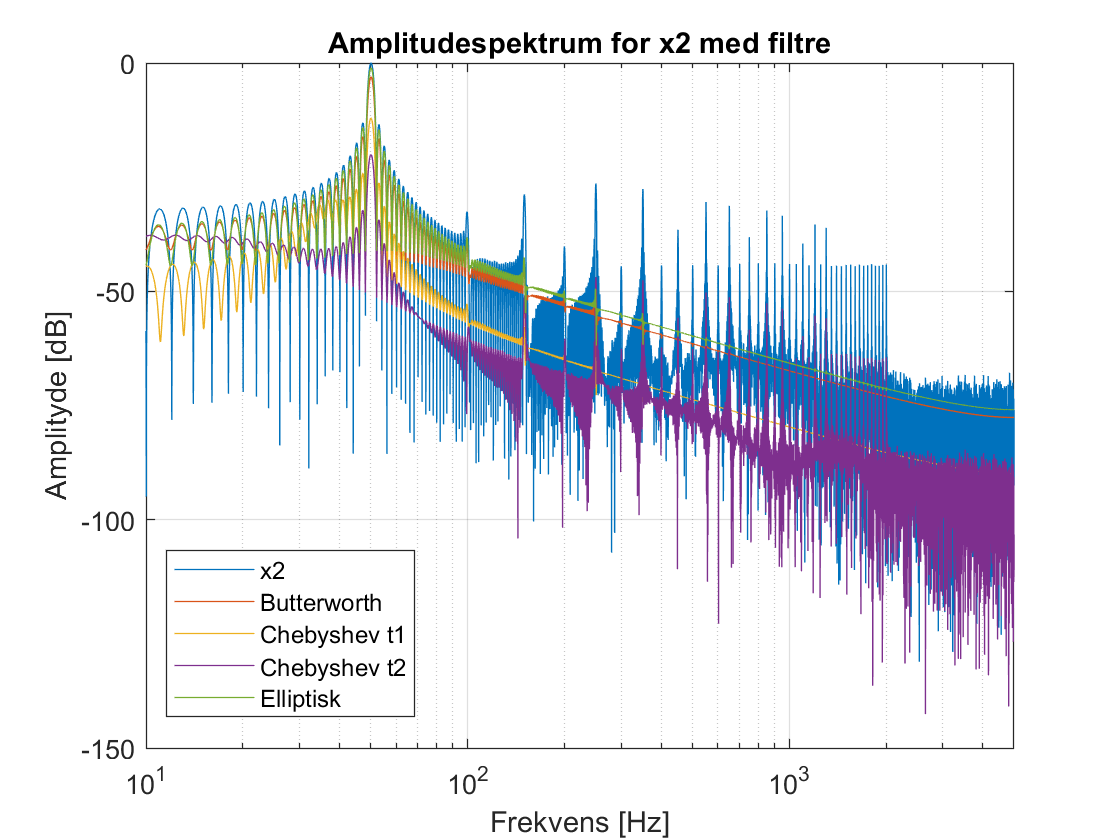

DFTx2butter = 2/N * abs(fft(x2butter,Nny));    % DFT x2 af Butterworth filtret
DFTx2cheby = 2/N * abs(fft(x2cheby,Nny));      % DFT x2 af Chebyshev type 1 filtret
DFTx2cheby2 = 2/N * abs(fft(x2cheby2,Nny));    % DFT x2 af Chebyshev type 2 filtret
DFTx2ellip = 2/N * abs(fft(x2ellip,Nny));      % DFT x2 af et eliptisk filtret

semilogx(f,20*log10(DFTx2))                    % Plot af x2 samt de 4 påtrygte filtre
hold on
semilogx(f,20*log10(DFTx2butter))       
semilogx(f,20*log10(DFTx2cheby))      
semilogx(f,20*log10(DFTx2cheby2))       
semilogx(f,20*log10(DFTx2ellip))       
xlim([10,fs/2]);                               % x-akse skalering
hold off
grid on
title('Amplitudespektrum for x2 med filtre')           
xlabel('Frekvens [Hz]')
ylabel('Amplityde [dB]')
legend("x2","Butterworth","Chebyshev t1", "Chebyshev t2", "Elliptisk","Location","best")

Ud fra amplitudespektret ses også at det Elliptiske filter følger signalet x2 bedst, men at Butterworth ligger meget tæt på. Men det Elliptiske filter har en højere amplitude end Butterworth filtret, og derfor det bedst velegnede filter til denne opgave. 

Vi vælger derfor at arbejde videre med det **Elliptiske** filter til næste afsnit om Zero crossing algoritme.

#### Zero crossing algoritme

Nu vil en algoritme der beregner frekvensen for signalet blive implementeret. Dette gøres ved at registrere hvornår signalets fortegn skifter fra negativ til positiv og så igen fra positiv til negativ, eller omvendt, da man her ved at der må have gået en halv periode. Nu vil den eksplicitte funktion blive beskrevet.

Funtionen er kald *zeroCrossing*, og den tager to argumenter, et signal [x] og sampling frekvensen [fs]. Den returnerer så den fundamentale frekvens [f].

%function [f] = zeroCrossing(x,fs)
%flag = 0;

Der laves et for loop som tjekker om fortegnet skifter minus til plus. sker dette gemmes samplingnummeret og en beregning for afstanden tilnulpunktet udførs og gemmes.

%for i = 2:n 
%    if (x(i-1) < 0 && x(i) > 0)
%        N1=i-1;
%        Na1=x(i-1)/(x(i-1)-x(i));
%        for c = i:n
%            if (x(c-1) > 0 && x(c) < 0)
%                N2=c-1;
%                Na2=x(c-1)/(x(c-1)-x(c));
%                flag = 1;
%                break;
%            end
%        end

Efter startes et nyt for loop hvor der herfra tjekkes om fortegnet skifter fra plus til minus. Nu dette er fundet, ved man at der er gået en halv periode og der hoppes ud af alle for loops.

Her under tjekkes det samme, bare med omvendt fortegn.

%    elseif(x(i-1) > 0 && x(i) < 0) 
%        N1=i-1;
%        Na1=x(i-1)/(x(i-1)-x(i));
%        for c = i:n
%            if (x(c-1) < 0 && x(c) > 0)
%                N2=c-1;
%                Na2=x(c-1)/(x(c-1)-x(c));
%                flag = 1;
%                break;
%            end
%        end
%    end
%    if flag == 1
%        break;
%    end
%end

Til sidst beregnes periode tiden med den givne formel fra opgaven, og frekvensen kan nu beregnes og returneres.

%T12=(2*(N2+Na2-(N1+Na1)))*1/fs;
%f = 1/T12;
%end

Vi vil nu lave en test for om funktionen virker efter hensigtet, ved at afprøve den på et perfekt sinus signal. Her sættes frekvensen til 50.1111 Hz.

f0=50.1111;             %Grundfrekvens.
nyts=1/fs;              %Periodetid.
t1 = 0:nyts:1;          %Varighed.
s_1=sin(2*pi*f0*t1);    %Sinussignal.
zeroCrossing(s_1,fs)    %Funktion anvendes.

ans = 50.1111

Vi kan dermed se at funktionen virker efter hensigten.

Nu anvendes funktionen på det filtrerede signal med 40 harmoniske.

zeroCrossing(x2ellip,fs) %Test af funktion på x2 med eliptisk filter, med den dominerende frekvens som cutoff.

ans = 38.3612

Vi kan se at filtret afvigere for meget, men vi ved at funktionen virker. Vi har fundet ud af at det afhænger filteret, mere specifikt cut-off frekvensen. Derfor beregnes hvilken cut-off der skal anvendes for at være inde for intervallet.

newCutoff = 0;
margin=0.001; %Magin for afvigelse.
for testfc=1:0.1:200 %Test for optimal cutoff.
    [ellipB,ellipA] = ellip(2,1,50,2*testfc/fs,"low");
    x2ellip = filter(ellipB,ellipA,x2);     % Signal x1 påtrykkes med et eliptisk filtret
    x2ellip = ifft(2/N*abs(fft(x2ellip,Nny)));
    testFrequency = zeroCrossing(x2ellip,fs);
    if testFrequency < 50.1111+margin && testFrequency > 50.1111-margin
        newCutoff = testfc;
        break;
    end
end
newCutoff %Ny cutoff frekvens til det eliptiske filter.

newCutoff = 59.9000

testFrequency %Ny frekvens med kun 0.2mHz afvigelse.

testFrequency = 50.1109

Vi har dermed nu fundet den cutoff frekvens hvor man kan være inde for afvigelsen på +- 10mHz, hvor den fundamentale frekvens bliver 50.1109 Hz.

## Konklusion

Vi har i denne opgave analyseret et filter med 40 harmoniske overtoner. Ud fra dette har vi fundet det bedst egnede anden ordens IIR filter ud af fire typer, der kan dæmpe overtonerne. Efterfølgende har vi lavet en algoritme der finde den fundamentale frekvens i et signal. Det filtrerede signal er blevet anvendt i algoritmen for at finde grundfrekvensen som overholder afvigelseskravet. Vi fandt ud af at cutoff frekvensen har en indflydelse på hvordan grundfrekvensen vil blive efter signalet bliver påtrykket med filteret. Derfor udviklede en algoritme til estimere den laveste cutoff frekvens inden for en specifik margin. Afslutningsvis kan vi konkludere at vi kunne finde frem til grundfrekvensen inde for de givne interval.